clc; clear;
syms Vf

% Fiber volume fractions
Vf_val = linspace(0, 1, 101);

% Fiber properties
E_f = 80;
G_f = 33.33;
v_f = 0.2;
K_f = E_f / (3 * (1 - 2 * v_f));

% Matrix properties
E_m = 4.2;
v_m = 0.34;
G_m = E_m / (2 * (1 + v_m));
K_m = E_m / (3 * (1 - 2 * v_m));

% Predefine arrays for results
E1_c_val = zeros(size(Vf_val));
v12_c_val = zeros(size(Vf_val));
k23_c_val = zeros(size(Vf_val));
G12_c_val = zeros(size(Vf_val));
G23_c_val = zeros(size(Vf_val));
E2_c_val = zeros(size(Vf_val));
v23_c_val = zeros(size(Vf_val));
v21_c_val = zeros(size(Vf_val));

r = G_f / G_m;
eta_m = 3 - 4 * v_m;
eta_f = 3 - 4 * v_f;

for i = 1:length(Vf_val)
    Vf_i = Vf_val(i);

    % A and B for E1 and v12
    A = (1 - Vf_i) * G_m / (K_f + 0.5 * G_f);
    B = Vf_i * G_m / (K_m + G_m / 3);

    % E1*
    E1_cca = Vf_i * E_f + (1 - Vf_i) * E_m + ...
        (4 * Vf_i * (1 - Vf_i) * (v_f - v_m)^2 * G_m) / (A + B + 1);
    E1_c_val(i) = E1_cca;

    % v12*
    v12_cca = (1 - Vf_i) * v_m + Vf_i * v_f + ...
        (Vf_i * (1 - Vf_i) * (v_f - v_m) * ...
        (G_m / (K_m + G_m / 3) - G_m / (K_f + G_f / 3))) / (A + B + 1);
    v12_c_val(i) = v12_cca;

    % k23*
    k23_cca = K_m + G_m / 3 + Vf_i / ...
        (1 / ((K_f - K_m) + (G_f - G_m) / 3) + (1 - Vf_i) / (K_m + 4 * G_m / 3));
    k23_c_val(i) = k23_cca;

    % G12*
    G12_cca = G_m * ((G_f * (1 + Vf_i) + G_m * (1 - Vf_i)) / ...
        (G_f * (1 - Vf_i) + G_m * (1 + Vf_i)));
    G12_c_val(i) = G12_cca;

    % G23* from roots
    a = 3 * Vf_i * (1 - Vf_i)^2 * ((r - 1) * (r + eta_f));
    b = (r * eta_m + eta_f * eta_m - Vf_i^3 * (r * eta_m - eta_f)) * ...
        (eta_m * Vf_i * (r - 1) - (r * eta_m + 1));
    A_G23 = a + b;

    B_G23 = -6 * Vf_i * (1 - Vf_i)^2 * ((r - 1) * (r + eta_f)) + ...
        (r * eta_m + (r - 1) * Vf_i + 1) * ...
        ((eta_m - 1) * (r + eta_f) - 2 * Vf_i^3 * (r * eta_m - eta_f)) + ...
        Vf_i * (r - 1) * (eta_m + 1) * (r + eta_f + Vf_i^3 * (r * eta_m - eta_f));

    D_G23 = 3 * Vf_i * (1 - Vf_i)^2 * ((r - 1) * (r + eta_f)) + ...
        (r * eta_m + Vf_i * (r - 1) + 1) * ...
        (r + eta_f + Vf_i^3 * (r * eta_m - eta_f));

    % Solve for G23
    coeffs = [A_G23, B_G23, D_G23];
    roots_G23 = roots(coeffs);
    real_pos_roots = roots_G23(imag(roots_G23) == 0 & real(roots_G23) > 0);
    if ~isempty(real_pos_roots)
        G23_c_val(i) = real_pos_roots(1) * G_m;
    else
        G23_c_val(i) = NaN; % mark as undefined if no valid root
    end

    % E2*
    E2_cca = (4 * G23_c_val(i) * k23_cca) / ...
         (k23_cca + G23_c_val(i) + (4 * v12_cca^2 * G23_c_val(i) * k23_cca) / E1_cca);
    E2_c_val(i) = E2_cca;

    % v23*
    v23_cca = (k23_cca - G23_c_val(i) - (4 * v12_cca^2 * G23_c_val(i) * k23_cca) / E1_cca) / ...
          (k23_cca + G23_c_val(i) + (4 * v12_cca^2 * G23_c_val(i) * k23_cca) / E1_cca);
    v23_c_val(i) = v23_cca;

    % v21*
    v21_cca = (4 * v12_cca * G23_c_val(i) * k23_cca) / ...
          (E1_cca * (k23_cca + G23_c_val(i)) + 4 * v12_cca^2 * G23_c_val(i) * k23_cca);
    v21_c_val(i) = v21_cca;
end
G12_c_val

G12_c_val =     1.5672    1.5960    1.6253    1.6552    1.6856    1.7166    1.7482    1.7805    1.8133    1.8468    1.8810    1.9159    1.9515    1.9878    2.0249    2.0627    2.1014    2.1409    2.1813    2.2225    2.2647    2.3078    2.3519    2.3970    2.4432    2.4905    2.5388    2.5884    2.6391    2.6912    2.7445    2.7992    2.8552    2.9128    2.9718    3.0324    3.0947    3.1587    3.2244    3.2920    3.3616    3.4332    3.5068    3.5827    3.6609    3.7415    3.8246    3.9104    3.9989    4.0904


G23_c_val

G23_c_val =     1.5672    1.5908    1.6148    1.6393    1.6644    1.6900    1.7161    1.7429    1.7702    1.7983    1.8270    1.8564    1.8866    1.9175    1.9493    1.9819    2.0154    2.0499    2.0853    2.1217    2.1592    2.1977    2.2374    2.2783    2.3204    2.3638    2.4086    2.4547    2.5022    2.5513    2.6019    2.6541    2.7081    2.7637    2.8212    2.8806    2.9420    3.0054    3.0709    3.1387    3.2087    3.2812    3.3561    3.4336    3.5138    3.5969    3.6828    3.7719    3.8641    3.9596


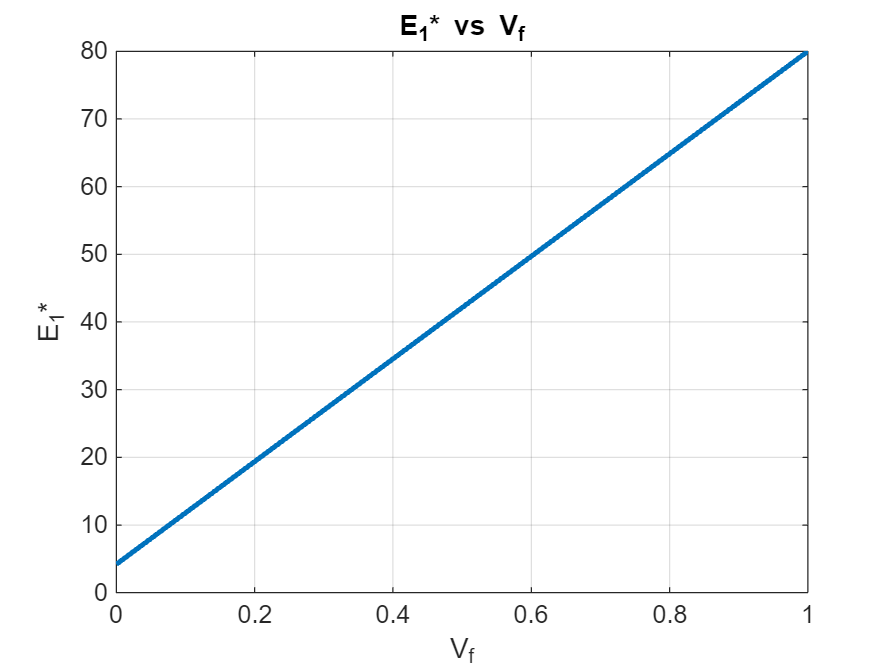

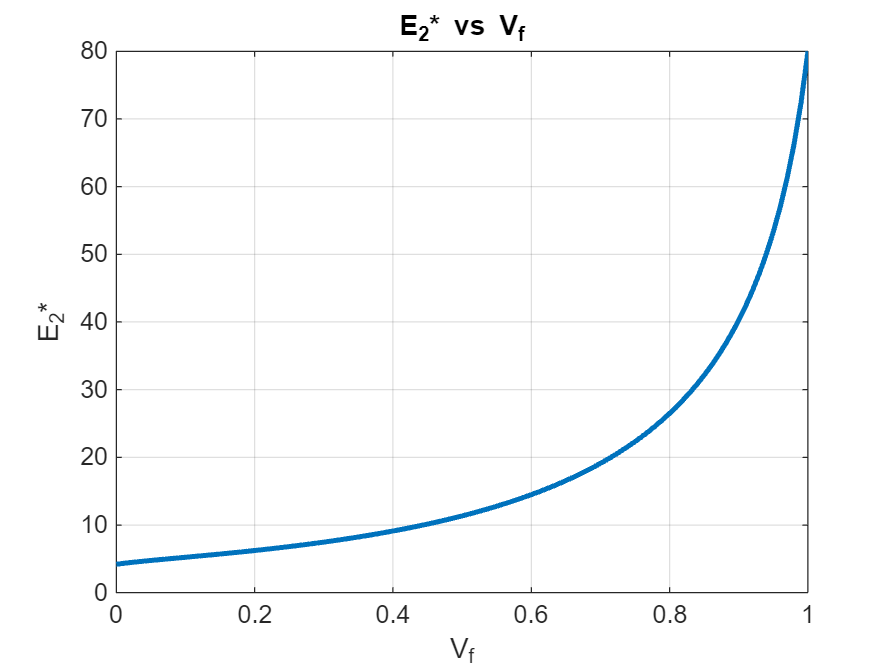

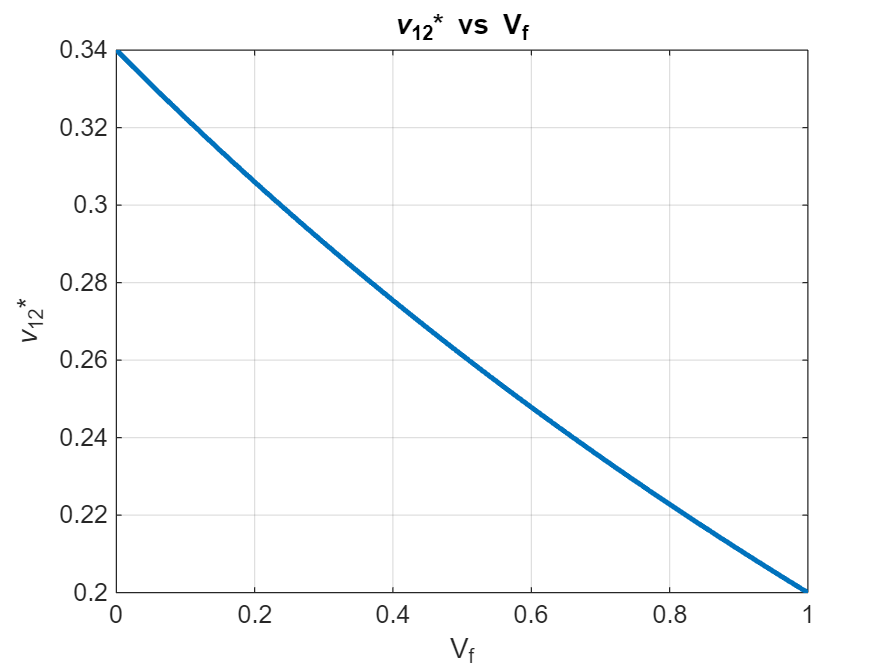

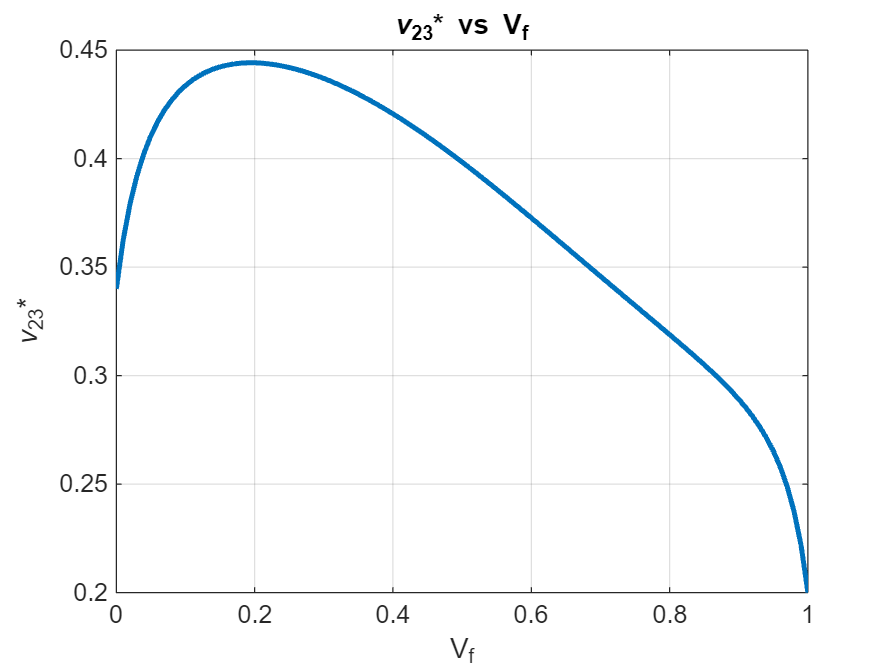

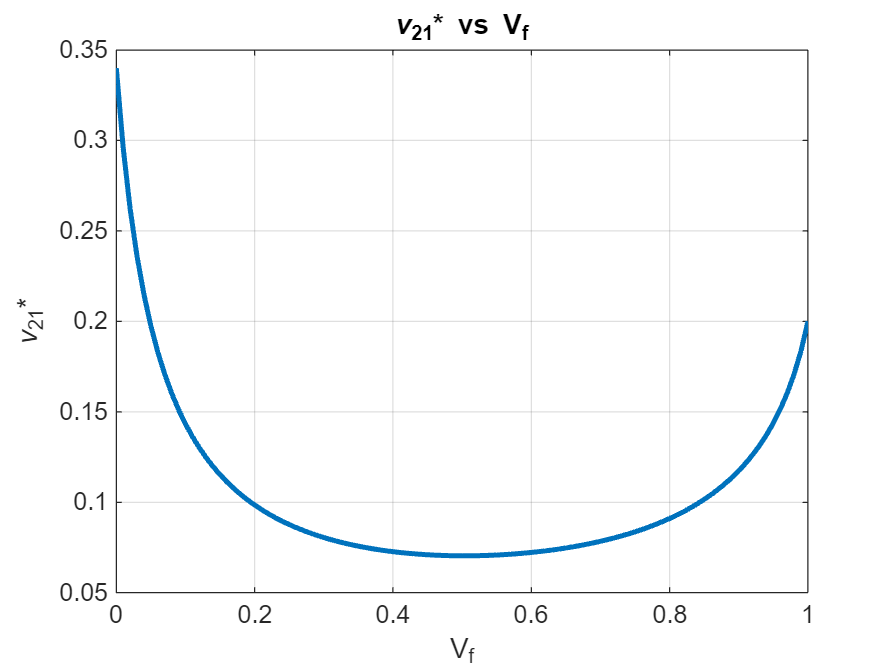

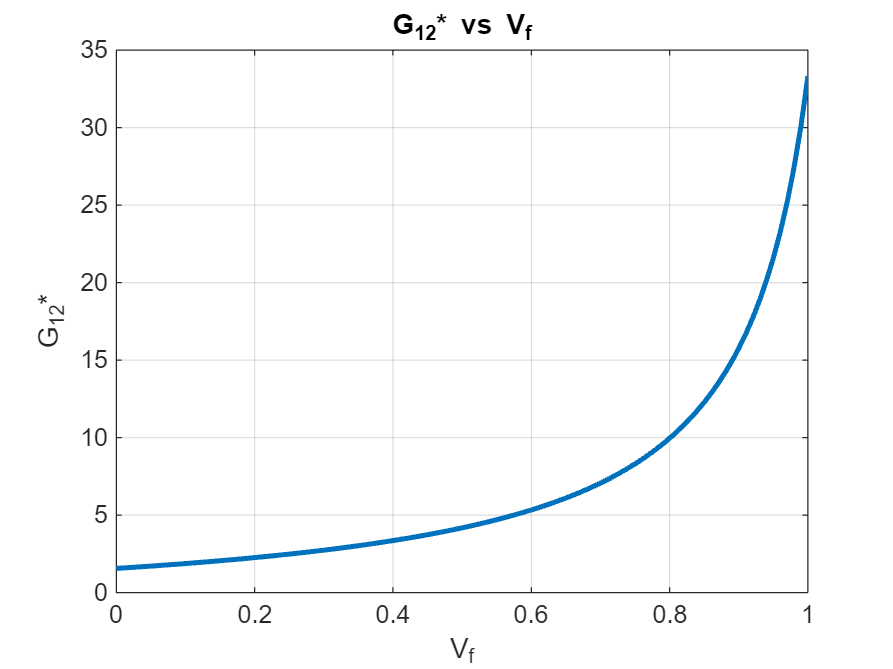

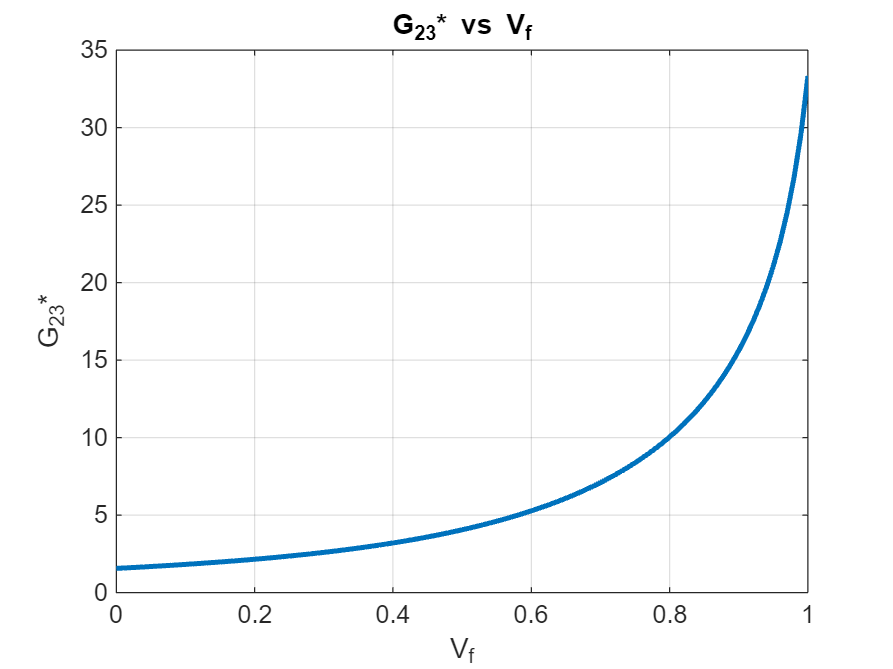

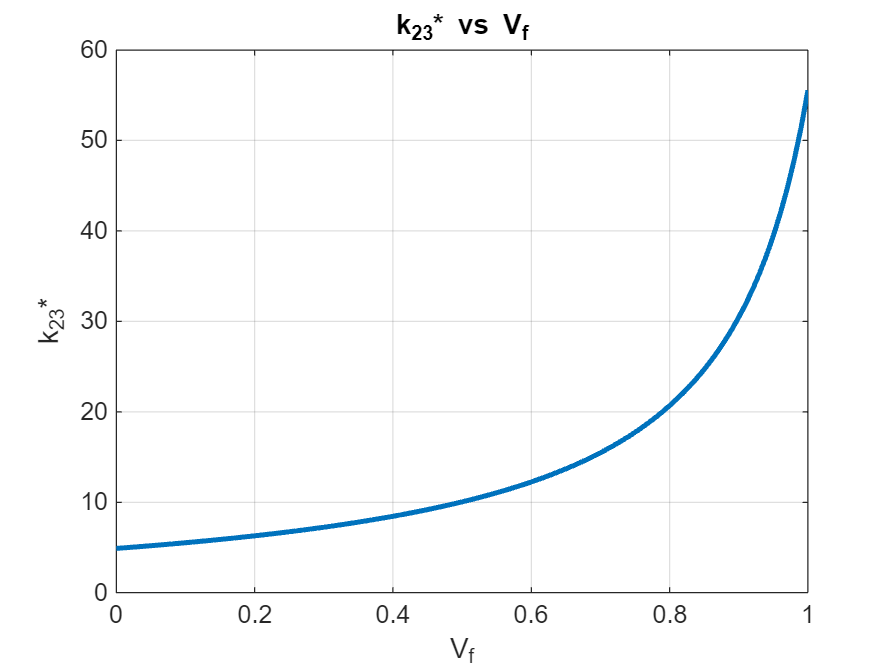

% Plotting
props = {E1_c_val, E2_c_val, v12_c_val, v23_c_val, v21_c_val, ...
         G12_c_val, G23_c_val, k23_c_val};
titles = {'E_1*', 'E_2*', '\nu_{12}*', '\nu_{23}*', '\nu_{21}*', ...
          'G_{12}*', 'G_{23}*', 'k_{23}*'};

for i = 1:length(props)
    figure;
    plot(Vf_val, props{i}, 'LineWidth', 2);
    title([titles{i} ' vs V_f']);
    xlabel('V_f'); ylabel(titles{i});
    grid on;
end